# Sample Generator

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

Expert data generation for behavioural cloning

clc
clear all
close all
generate_data = true;         % Run data generation simulation

buffer_name   = 'train100k'; % train/validation
Nepisodes     = 100000;      % Number of simulations

% buffer_name   = 'train10k'; % train/validation
% Nepisodes     = 10000;      % Number of simulations

% buffer_name   = 'validation'; % train/validation
% Nepisodes     = 1000;         % Number of simulations

% Randomness control
if contains(buffer_name, 'train')
    0
    rng(0)
elseif strcmp(buffer_name, 'validation')
    1
    rng(1)
end

ans = 0

## Parameters

Simulation and control steps

fs = 6e3;
Ts = 1/fs;    % Sampling time
Ni = 40;
Ti = Ts/Ni;	    % Integration step

Ax0 = 4*130

Ax0 = 520

Ay0 = 380*sqrt(2/3)

Ay0 = 310.2687

wx0 = 0;
wy0 = 2*pi*50;

[ix_max, iy_max, is_max, vo_max, vB_max, VCdiff, eta] = max_values(Ax0, Ay0, 'M2C')

ix_max = 3.5800

iy_max = 4

is_max = 8.5000

vo_max = 415.1344

vB_max = 830.2687

VCdiff = 0.0100

eta = 1.7214

## Modular Multilevel Cascaded Converter (MMCC)

Specifications

specsMMCC = struct();

specsMMCC.Topology = 'M2C';    % Converter topology M3C/M2C
specsMMCC.Ti       = Ti;       % Integration step
specsMMCC.R        = 0.2;      % Branch resistance
specsMMCC.L        = 5e-3;     % Branch inductance
specsMMCC.Csm      = 987e-6;   % Submodule capacitance
specsMMCC.Nsm      = 4;        % Submodules per cluster
specsMMCC.Rx       = 1e-3;     % Input filter resistance
specsMMCC.Lx       = 0.1e-3;   % Input filter inductance
specsMMCC.Ry       = 1;        % Output filter resistance
specsMMCC.Ly       = 200e-3;   % Output filter inductance

Initial values

init_valsMMCC = struct();

if strcmp(specsMMCC.Topology, 'M3C')
    init_valsMMCC.is0 = zeros(9, 1);                     % Cluster current
    init_valsMMCC.vc0 = (vB_max + vo_max) * ones(9, 1);  % Cluster capacitor voltage
elseif strcmp(specsMMCC.Topology, 'M2C')
    init_valsMMCC.is0 = zeros(6, 1);                     % Cluster current
    init_valsMMCC.vc0 = (vB_max + vo_max) * ones(6, 1);  % Cluster capacitor voltage
end

Create object

MMCC = ClassMMCC(specsMMCC, init_valsMMCC)

MMCC =   ClassMMCC with properties:

    Topology: 'M2C'
           A: [5×6 double]
       pinvA: [6×5 double]
           m: 6
           N: [6×2 double]
           n: 2
       pinvN: [2×6 double]
           p: 2
           q: 3
          Ti: 4.1667e-06
           R: 0.2000
           L: 0.0050
         Csm: 9.8700e-04
         Nsm: 4
           C: 2.4675e-04
          Rx: 1.0000e-03
          Lx: 1.0000e-04
          Ry: 1
          Ly: 0.2000
          As: [6×6 double]
          Bs: [6×6 double]
          Ad: [6×6 double]
          Bd: [6×6 double]
         ixy: [5×1 double]
          is: [6×1 double]
          iB: [6×1 double]
          iz: [6×1 double]
          ie: [2×1 double]
          vc: [6×1 double]
          Ec: [6×1 double]

## External system (IOGrid)

Specifications

specsIOGrid = struct();

specsIOGrid.Ti = Ti;
specsIOGrid.Ax = Ax0;
specsIOGrid.Ay = Ay0;
specsIOGrid.p  = MMCC.p;
specsIOGrid.q  = MMCC.q;

Initial values

init_valsIOGrid = struct();

init_valsIOGrid.gx0 = 0;
init_valsIOGrid.gy0 = 0;
init_valsIOGrid.wx0 = wx0;
init_valsIOGrid.wy0 = wy0;

Create object

IOGrid = ClassIOGrid(specsIOGrid, init_valsIOGrid)

IOGrid =   ClassIOGrid with properties:

     Ti: 4.1667e-06
     Ax: 520
     Ay: 310.2687
      p: 2
      q: 3
     wx: 0
     wy: 314.1593
     gx: 0
     gy: 0
    vxy: [5×1 double]

## Cluster Energy Model Predictive Controller (CEMPC)

Cluster energy and capacitor voltage references

vc_mean_ref = vB_max + vo_max

vc_mean_ref = 1.2454e+03

Ec_mean_ref = MMCC.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(MMCC.m, 1);
Ec_ref = Ec_mean_ref * ones(MMCC.m, 1);

Specifications

specsCEMPC = struct();

specsCEMPC.Ts        = Ts;
specsCEMPC.MMCC      = MMCC;
specsCEMPC.is_max    = is_max;
specsCEMPC.vo_max    = vo_max;
% specsCEMPC.lambda_z  = (Ec_mean_ref/is_max)^2 * 0.2e-3;
% specsCEMPC.lambda_o  = (Ec_mean_ref/vo_max)^2 * 0.5e-3;
specsCEMPC.lambda_z  = (Ec_mean_ref/is_max)^2 * 2e-3;
specsCEMPC.lambda_o  = (Ec_mean_ref/vo_max)^2 * 5e-3;
specsCEMPC.lambda_dz = (Ec_mean_ref/is_max)^2 * 2e-6 * 0;
specsCEMPC.lambda_do = (Ec_mean_ref/vo_max)^2 * 2e-6 * 0;
specsCEMPC.lmax      = 10;
% specsCEMPC.Np        = 1;
specsCEMPC.Np        = 10;

specsCEMPC.lambda_z% = 0.085;

ans = 1.0136

specsCEMPC.lambda_o% = 0.0001; 

ans = 0.0011

Create object

CEMPC = ClassCEMPC(specsCEMPC)

CEMPC =   ClassCEMPC with properties:

             Ts: 1.6667e-04
              m: 6
              n: 2
             NN: [60×20 double]
            one: [60×10 double]
             IM: [60×60 double]
            IM2: [60×60 double]
              K: [60×60 double]
             Np: 10
         is_max: 8.5000
         vo_max: 415.1344
       lambda_z: 1.0136
       lambda_o: 0.0011
      lambda_dz: 0
      lambda_do: 0
           lmax: 10
      options_i: [1×1 mpcActiveSetOptions]
      options_v: [1×1 mpcActiveSetOptions]
         ie_ref: [2×1 double]
         iz_ref: [6×1 double]
         vo_ref: 0
    ie_ref_prev: [20×1 double]
    iz_ref_prev: [60×1 double]
    vo_ref_prev: [10×1 double]
            iAi: [120×1 logical]
            iAv: [20×1 logical]
     exitflag_i: -3
     exitflag_v: -3
       exitflag: -3
            Tex: 0

## Reference Frame Transform (RFT)

RFT = reference_frame_transforms();
RFT.abc2dq

ans = function_handle with value:
    @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]

RFT.abc2ab

ans =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774


RFT.ab2abc

ans =     1.0000         0
   -0.5000    0.8660
   -0.5000   -0.8660


## Basic Variables Predictor (P)

Predict external voltages and currents for the Cluster Energy MPC

Specifications

specsP = struct();

specsP.MMCC  = MMCC;
specsP.CEMPC = specsCEMPC;
specsP.RFT   = RFT;

Create object

P = BasicVariablesPredictor(specsP)

P =   BasicVariablesPredictor with properties:

     Np: 10
     Ts: 1.6667e-04
    RFT: [1×1 struct]
      A: [5×6 double]
      p: 2
      q: 3

## Buffer

Initialize buffer

Ninputs = 1 + MMCC.m + 6;
% mean(Ec), Ec-mean(Ec)
% iya, iyb, vyac, vybc, py1, py2

if strcmp(MMCC.Topology, 'M3C')
    Ninputs = Ninputs + 6;
    % ixa, ixb, vxac, vxbc, px1, px2
elseif strcmp(MMCC.Topology, 'M2C')
    Ninputs = Ninputs + 1;
    % ix (vx is constant, px=vx*ix, px is just a scaled version of ix)
end
Ninputs

Ninputs = 14


Noutputs = MMCC.n + 1

Noutputs = 3

% ie (n), vo

Buffer has $N_{\textrm{episodes}}$ observations and actions of dimensions $N_{\textrm{inputs}}$ and $N_{\textrm{outputs}}$, respectively

buffer   = struct();
buffer.X = zeros(Nepisodes, Ninputs);
buffer.Y = zeros(Nepisodes, Noutputs);
buffer

buffer = struct with fields:
    X: [100000×14 double]
    Y: [100000×3 double]

Number of active constraints per example

active_constraints_list = zeros(2, Nepisodes);

Exit flag to remove unfeasible examples

exitflag_list = zeros(1, Nepisodes);

## Generate input data

Create grid

Ninit_vals = MMCC.m + MMCC.n + 5;
% vc, ie, iy, ix, gvy, giy, wy

if strcmp(MMCC.Topology, 'M3C')
    Ninit_vals = Ninit_vals + 3; % gvx, gix, wx
end
Ninit_vals

Ninit_vals = 13


init_vals = lhsdesign(Nepisodes, Ninit_vals)';
size(init_vals)

ans =           13      100000


Select grid variables

VC0  = 2*init_vals(1:MMCC.m, :)-1;
IE0  = 2*init_vals(MMCC.m+1:MMCC.m+MMCC.n, :)-1;
IY0  = init_vals(MMCC.m+MMCC.n+1, :);
IX0  = init_vals(MMCC.m+MMCC.n+2, :);
GVY0 = init_vals(MMCC.m+MMCC.n+3, :)*2*pi;
GIY0 = init_vals(MMCC.m+MMCC.n+4, :)*2*pi;
WY0  = 2*init_vals(MMCC.m+MMCC.n+5, :)-1;

if strcmp(MMCC.Topology, 'M3C')
    GVX0 = init_vals(MMCC.m+MMCC.n+6, :)*2*pi;
    GIX0 = init_vals(MMCC.m+MMCC.n+7, :)*2*pi;
    WX0  = 2*init_vals(MMCC.m+MMCC.n+8, :)-1;
end

Scale to physical units

% Cluster voltages
VC0 = (VC0 * VCdiff + 1) * vc_mean_ref;

% Output currents
IY0 = RFT.ab2abc * (iy_max * IY0.^(1/2.4) .* [cos(GIY0); sin(GIY0)]);

% Input currents
if strcmp(MMCC.Topology, 'M3C')
    IX0 = RFT.ab2abc * (ix_max * IX0.^(1/2.4) .* [cos(GIX0); sin(GIX0)]);
elseif strcmp(MMCC.Topology, 'M2C')
    IX0 = ix_max * (2*IX0-1) .* [1; -1];
end

% Basic currents
IXY0 = [IX0; IY0];
IB0  = MMCC.pinvA * IXY0;

% Circulating currents
IZ0 = MMCC.N * IE0;
alpha_min = @(alpha) abs(max(abs(IB0(:) + IZ0(:) * alpha)) - is_max);
alpha = fminbnd(alpha_min, 0, 100)

alpha = 2.8231

IZ0 = IZ0 * alpha;
IE0 = MMCC.pinvN * IZ0;

% Cluster currents
IS0 = IB0 + IZ0;

max(abs(IS0(:)))

ans = 8.5000

max(abs(IB0(:)))

ans = 3.1911

max(abs(IX0(:)))

ans = 3.5800

max(abs(IY0(:)))

ans = 3.9999

max(abs(IZ0(:)))

ans = 5.6332

max(abs(IE0(:)))

ans = 2.8231


% Output angular frequency
WY0 = WY0 * 50;

% Input angular frequency
if strcmp(MMCC.Topology, 'M3C')
    WX0 = WX0 * 50;
end

Save initialization values

buffer_init = struct();

buffer_init.VC0  = VC0;
buffer_init.IS0  = IS0;
buffer_init.GVY0 = GVY0;
buffer_init.WY0  = WY0;

if strcmp(MMCC.Topology, 'M3C')
    buffer_init.GVX0 = GVX0;
    buffer_init.WX0 = WX0;
end

save(strcat('ImitationLearning\TrainingData\Data\init_', buffer_name, '.mat'), 'buffer_init')

## Generate output data

if generate_data

init_valsIOGrid = struct();
init_valsM3C = struct();

% Initialize progress bar
h = waitbar(0, 'Generating Data...');

tic
for episode = 1:Nepisodes

% Reset CEMPC solver
CEMPC = CEMPC.reset();

% MMCC
init_valsM3C.vc0 = VC0(:, episode);
init_valsM3C.is0 = IS0(:, episode);
MMCC = MMCC.reset(init_valsM3C);
Ec   = MMCC.Ec;
vc   = MMCC.vc;
iB   = MMCC.iB;
ixy  = MMCC.ixy;

% Input/output grid voltages
init_valsIOGrid.gy0 = GVY0(episode);
init_valsIOGrid.wy0 = WY0(episode);
if strcmp(MMCC.Topology, 'M3C')
    init_valsIOGrid.gx0 = GVX0(episode);
    init_valsIOGrid.wx0 = WX0(episode);
end
IOGrid = IOGrid.reset(init_valsIOGrid);
vxy = IOGrid.vxy;
vB = MMCC.A' * vxy;

% Predict basic variables
vB_pred = P.predict(vxy, IOGrid.wx, IOGrid.wy);
iB_pred = P.predict(ixy, IOGrid.wx, IOGrid.wy);

% Cluster energy MPC
CEMPC = CEMPC.control(Ec, vB_pred, iB_pred, vc);

% Add to buffer
iya_iyb   = ixy(MMCC.p+1:end-1);
vyac_vybc = vxy(MMCC.p+1:end-1) - vxy(end);
py        = vyac_vybc .* iya_iyb;

buffer.X(episode, 1)                 = mean(Ec);
buffer.X(episode, 2:1+MMCC.m)        = Ec - mean(Ec);
buffer.X(episode, 2+MMCC.m:3+MMCC.m) = iya_iyb;
buffer.X(episode, 4+MMCC.m:5+MMCC.m) = vyac_vybc;
buffer.X(episode, 6+MMCC.m:7+MMCC.m) = py;

if strcmp(MMCC.Topology, 'M3C')
    ixa_ixb   = ixy(1:MMCC.p-1);
    vxac_vxbc = vxy(1:MMCC.p-1) - vxy(MMCC.p);
    px        = vxac_vxbc .* ixa_ixb;

    buffer.X(episode, 8+MMCC.m:9+MMCC.m)   = ixa_ixb;
    buffer.X(episode, 10+MMCC.m:11+MMCC.m) = vxac_vxbc;
    buffer.X(episode, 12+MMCC.m:end)       = px;
elseif strcmp(MMCC.Topology, 'M2C')
    ix = ixy(1);

    buffer.X(episode, 8+MMCC.m) = ix;   
end

buffer.Y(episode, 1:MMCC.n) = CEMPC.ie_ref;
buffer.Y(episode, end)      = CEMPC.vo_ref;

exitflag_list(episode) = CEMPC.exitflag;
active_constraints_list(1, episode) = sum(CEMPC.iAi);
active_constraints_list(2, episode) = sum(CEMPC.iAv);

% Update progress bar
waitbar(episode/Nepisodes, h, sprintf('Generating Data: %d%%', round((episode/Nepisodes)*100)));

end
toc

% Close progress bar
close(h)

end

Elapsed time is 0.019141 seconds.


Filter non feasible examples

mask = exitflag_list == 1;
buffer.X = buffer.X(mask, :)

buffer = struct with fields:
    X: [100000×14 double]
    Y: [100000×3 double]

buffer.Y = buffer.Y(mask, :)

buffer = struct with fields:
    X: [100000×14 double]
    Y: [100000×3 double]

Count active constraints

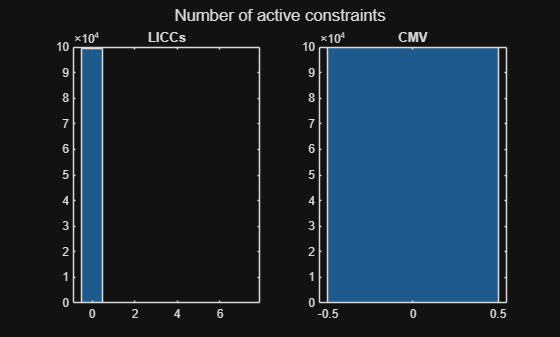

figure
subplot(1, 2, 1)
histogram(active_constraints_list(1, :))
title('LICCs')
subplot(1, 2, 2)
histogram(active_constraints_list(2, :))
title('CMV')
sgtitle('Number of active constraints')

Save generated data

buffer.X = buffer.X';
buffer.Y = buffer.Y';
save(strcat('ImitationLearning\TrainingData\Data\', buffer_name, '.mat'), 'buffer')